ft = fittype( 'poly6' );
[fitresult, gof] = fit( V, N, ft, 'Normalize', 'on' )

fitresult =      Linear model Poly6:
     fitresult(x) = p1*x^6 + p2*x^5 + p3*x^4 + p4*x^3 + p5*x^2 + 
                    p6*x + p7
       where x is normalized by mean 400 and std 66.33
     Coefficients (with 95% confidence bounds):
       p1 =       66.02  (-583.2, 715.2)
       p2 =      -227.1  (-679.8, 225.6)
       p3 =      -47.11  (-2299, 2205)
       p4 =       638.7  (-690.6, 1968)
       p5 =      -459.9  (-2460, 1540)
       p6 =       47.21  (-801.3, 895.7)
       p7 =        1029  (640.3, 1418)

gof = struct with fields:
           sse: 1.6483e+05
       rsquare: 0.9249
           dfe: 4
    adjrsquare: 0.8122
          rmse: 202.9991



figure( 'Name', 'POLYNOMIAL' );
h = plot( fitresult, V, N );
legend( h, 'Data', 'polyfit6', 'Location', 'NorthEast' );
% Label axes
xlabel 'Voltage(V)'
ylabel 'Number of Read Decays'
title 'PLATEAU'

hold on
v=300:20:500;
a=fitresult(v);
err=sqrt(a);
errorbar(v,a,err,'both','go')

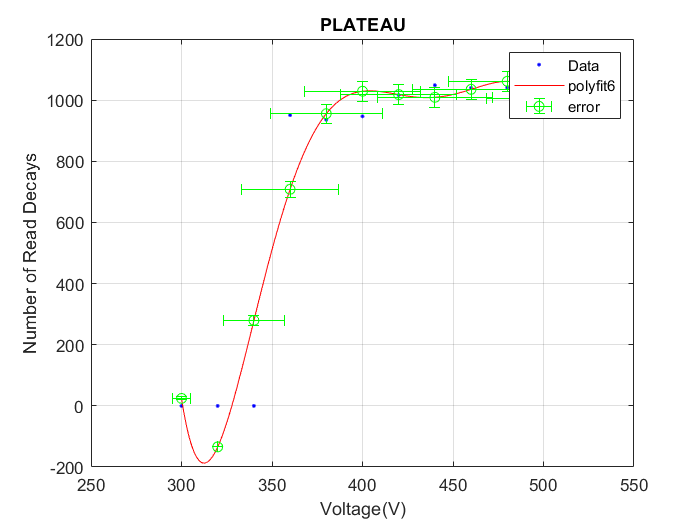

%since this is a polynomial fit some of the value are negative therefore
%there can be some warnings about its sqaure root  but i believe it works fine.
grid on

legend({'Data','polyfit6','error'},'Location','northeast')